%% =========================================================
%  MULTI-GROUP SCOUT RESULTS VS LESION
%
%  INPUTS:
%   - cortex exported from Brainstorm
%   - lesion scout exported separately (mask)
%   - group scouts exported separately:
%       spike, spikeHFO, HFO
%
%  OUTPUT:
%   - ResultsTable with:
%       * NumVertices
%       * ScoutArea_cm2
%       * DistanceMaxPoints_mm
%       * MeanDistance_mm
%       * MedianDistance_mm
%       * SpatialDispersion_RMS_mm
%       * StdDistance_mm
%   - Figure 1:
%       * Distance to lesion (one subplot per group)
%   - Figure 2:
%       * Comparative violin + boxplot + scatter for the 3 groups
%         using distance to lesion only
%   - HTML report with table + figures
%   - MAT file with numerical results
%% =========================================================

clear; clc; close all;

%% =========================
% 1) FILES: EDIT THESE PATHS
%% =========================

% >>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>
% CHANGE THIS PATIENT ID WHEN NEEDED
patient_id = 'FGS';
% <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<

cortex_file    = 'C:\Users\Poject Epilepsy\Documents\brainstorm_db\ESI_10-10_12-03-2026_FGS\anat\FGS\tess_cortex_central_low.mat';

mask_file      = 'C:\Users\Poject Epilepsy\Documents\datos_brainstorm\pacientes_rafa\FGS_done\scout_lesion_mask.mat';
spike_file     = 'C:\Users\Poject Epilepsy\Documents\datos_brainstorm\pacientes_rafa\FGS_done\scout_lesion_spike.mat';
spikeHFO_file  = 'C:\Users\Poject Epilepsy\Documents\datos_brainstorm\pacientes_rafa\FGS_done\scout_lesion_spikeHFO.mat';
HFO_file       = 'C:\Users\Poject Epilepsy\Documents\datos_brainstorm\pacientes_rafa\FGS_done\scout_lesion_HFO.mat';

% Brainstorm usually stores vertices in meters
% Multiply by 1000 to work in mm
unit_scale = 1000;


%% =========================
% 2) LOAD DATA
%% =========================

sCortex  = load(cortex_file);
mask     = load(mask_file);
spike    = load(spike_file);
spikeHFO = load(spikeHFO_file);
HFO      = load(HFO_file);

% --- Cortex vertices ---
if isfield(sCortex, 'Vertices')
    VerticesRaw = sCortex.Vertices;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Vertices')
    VerticesRaw = sCortex.sSurf.Vertices;
else
    error('No se ha encontrado el campo Vertices en el archivo del cortex.');
end

% --- Cortex faces ---
Faces = [];
if isfield(sCortex, 'Faces')
    Faces = sCortex.Faces;
elseif isfield(sCortex, 'sSurf') && isfield(sCortex.sSurf, 'Faces')
    Faces = sCortex.sSurf.Faces;
else
    warning('No se ha encontrado Faces. El cálculo del área del scout no funcionará.');
end

% Coordinates in mm
VerticesMM = VerticesRaw * unit_scale;


%% =========================
% 3) EXTRACT LESION SCOUT
%% =========================

maskScout = get_first_scout(mask, 'mask');

lesion_vertices = maskScout.Vertices;
lesion_seed     = get_scout_seed(maskScout);

if isempty(lesion_vertices)
    error('El scout de lesión no contiene vértices.');
end

lesion_coords_mm = VerticesMM(lesion_vertices, :);
lesion_seed_mm   = VerticesMM(lesion_seed, :);


%% =========================
% 4) DEFINE GROUPS
%% =========================

group_names  = {'Spike', 'Spike+HFO', 'HFO'};
group_files  = {spike, spikeHFO, HFO};

% Same colors as before
group_colors = [
    0.20 0.45 0.85   % blue
    0.85 0.40 0.20   % orange/red
    0.25 0.65 0.35   % green
];

nGroups = numel(group_names);

% Containers
group_vertices        = cell(nGroups,1);
group_coords_mm       = cell(nGroups,1);
group_seed_idx        = zeros(nGroups,1);
group_seed_mm         = zeros(nGroups,3);

vertex_distances      = cell(nGroups,1);

NumVertices               = zeros(nGroups,1);
ScoutArea_cm2             = zeros(nGroups,1);
DistanceMaxPoints_mm      = zeros(nGroups,1);
MeanDistance_mm           = zeros(nGroups,1);
MedianDistance_mm         = zeros(nGroups,1);
SpatialDispersion_RMS_mm  = zeros(nGroups,1);
StdDistance_mm            = zeros(nGroups,1);


%% =========================
% 5) COMPUTE METRICS FOR EACH GROUP
%% =========================

for g = 1:nGroups
    scoutStruct = get_first_scout(group_files{g}, group_names{g});

    group_vertices{g} = scoutStruct.Vertices;
    group_seed_idx(g) = get_scout_seed(scoutStruct);

    if isempty(group_vertices{g})
        error('El scout del grupo "%s" no contiene vértices.', group_names{g});
    end

    group_coords_mm{g} = VerticesMM(group_vertices{g}, :);
    group_seed_mm(g,:) = VerticesMM(group_seed_idx(g), :);

    % Number of vertices
    NumVertices(g) = numel(group_vertices{g});

    % Scout area in cm²
    if ~isempty(Faces)
        ScoutArea_cm2(g) = compute_scout_area_cm2(Faces, VerticesRaw, group_vertices{g}, unit_scale);
    else
        ScoutArea_cm2(g) = NaN;
    end

    % Distance between scout seeds (maximum intensity points)
    DistanceMaxPoints_mm(g) = norm(group_seed_mm(g,:) - lesion_seed_mm);

    % Pairwise distances: each group vertex vs all lesion vertices
    D = pdist2(group_coords_mm{g}, lesion_coords_mm);

    % For each group vertex, minimum distance to lesion
    dmin = min(D, [], 2);
    vertex_distances{g} = dmin;

    % Standard summaries
    MeanDistance_mm(g)          = mean(dmin);
    MedianDistance_mm(g)        = median(dmin);
    SpatialDispersion_RMS_mm(g) = sqrt(mean(dmin.^2));
    StdDistance_mm(g)           = std(dmin);
end


%% =========================
% 5b) COMMON X LIMIT FOR DISTANCE PLOTS
%% =========================

all_distance_values = [];

for g = 1:nGroups
    all_distance_values = [all_distance_values; vertex_distances{g}(:)]; %#ok<AGROW>
end

distance_xlim = get_shared_xlim(all_distance_values);


%% =========================
% 6) RESULTS TABLE
%% =========================

ResultsTable = table( ...
    group_names', ...
    NumVertices, ...
    ScoutArea_cm2, ...
    DistanceMaxPoints_mm, ...
    MeanDistance_mm, ...
    MedianDistance_mm, ...
    SpatialDispersion_RMS_mm, ...
    StdDistance_mm, ...
    'VariableNames', { ...
        'Group', ...
        'NumVertices', ...
        'ScoutArea_cm2', ...
        'DistanceMaxPoints_mm', ...
        'MeanDistance_mm', ...
        'MedianDistance_mm', ...
        'SpatialDispersion_RMS_mm', ...
        'StdDistance_mm'} ...
    );

disp('==========================================');

disp('RESULTS TABLE');

RESULTS TABLE


disp('==========================================');

disp(ResultsTable);

        Group        NumVertices    ScoutArea_cm2    DistanceMaxPoints_mm    MeanDistance_mm    MedianDistance_mm    SpatialDispersion_RMS_mm    StdDistance_mm
    _____________    ___________    _____________    ____________________    _______________    _________________    ________________________    ______________

    {'Spike'    }        24            1.8259               9.6215               9.5786              10.249                   10.293                 3.8475    
    {'Spike+HFO'}        23            1.1348               7.1427               2.6527              2.5911                   3.7736                 2.7443    
    {'HFO'      }        36            2.6333               73.919               63.494

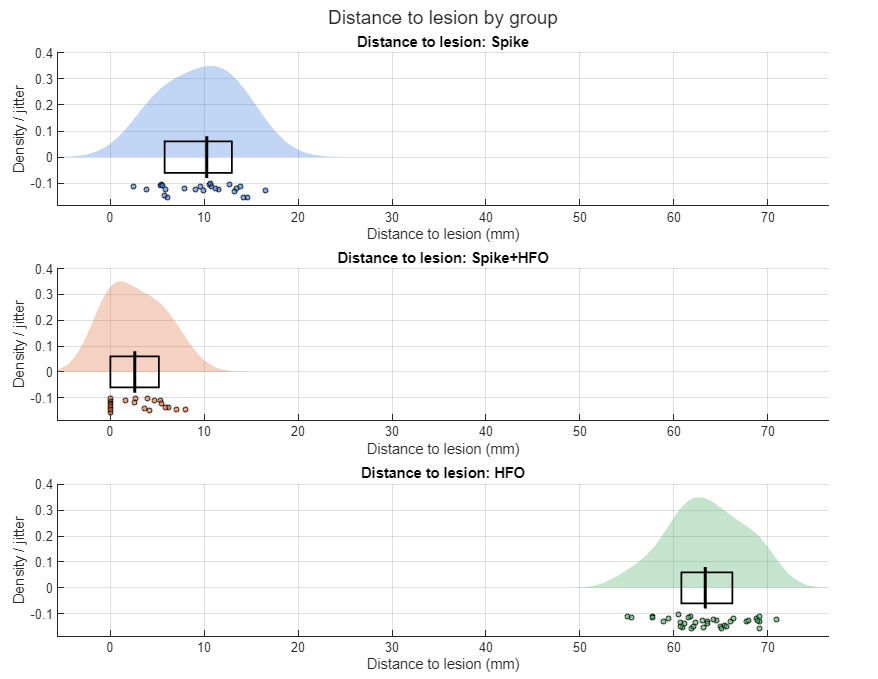

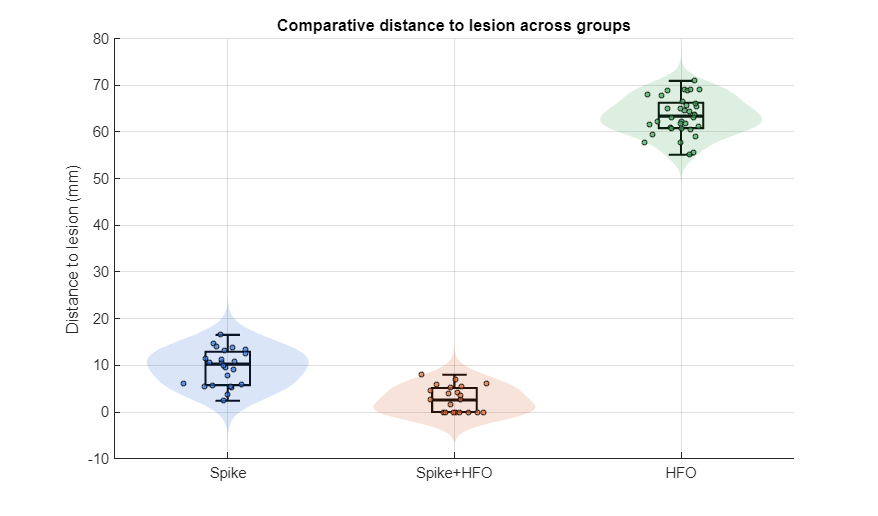



%% =========================
% 7) FIGURE 1: RAINCLOUD DISTANCE (SEPARATE SUBPLOTS)
%% =========================

fig1 = figure('Color','w','Position',[100 100 1100 850]);
tl1 = tiledlayout(nGroups,1,'TileSpacing','compact','Padding','compact');

for g = 1:nGroups
    ax = nexttile(tl1);
    plot_single_raincloud(ax, vertex_distances{g}, vertex_distances{g}, group_colors(g,:), ...
        ['Distance to lesion: ' group_names{g}], ...
        'Distance to lesion (mm)', ...
        distance_xlim);
end

title(tl1, 'Distance to lesion by group');


%% =========================
% 8) FIGURE 2: COMPARATIVE DISTANCE PLOT (3 GROUPS)
%% =========================

fig2 = figure('Color','w','Position',[140 140 850 500]);
plot_grouped_violin_boxscatter(vertex_distances, vertex_distances, group_names, group_colors, ...
    'Distance to lesion (mm)', ...
    'Comparative distance to lesion across groups');


%% =========================
% 9) SAVE RESULTS
%% =========================

output_folder = fileparts(spike_file);

base_name   = ['results_patient_' patient_id];
html_folder = fullfile(output_folder, base_name);
fig_folder  = fullfile(html_folder, 'figures');

html_file   = fullfile(html_folder, [base_name '.html']);
mat_file    = fullfile(html_folder, [base_name '.mat']);

if ~exist(html_folder, 'dir')
    mkdir(html_folder);
end
if ~exist(fig_folder, 'dir')
    mkdir(fig_folder);
end

all_figs = [fig1; fig2];
all_captions = { ...
    'Distance to lesion by group', ...
    'Comparative distance to lesion across groups'};

img_names = cell(numel(all_figs),1);

for i = 1:numel(all_figs)
    img_names{i} = sprintf('%s_figure_%02d.png', base_name, i);
    img_path = fullfile(fig_folder, img_names{i});
    exportgraphics(all_figs(i), img_path, 'Resolution', 300);
end


% Save MAT file with main outputs
save(mat_file, ...
    'ResultsTable', ...
    'group_names', ...
    'group_colors', ...
    'vertex_distances', ...
    'NumVertices', ...
    'ScoutArea_cm2', ...
    'DistanceMaxPoints_mm', ...
    'MeanDistance_mm', ...
    'MedianDistance_mm', ...
    'SpatialDispersion_RMS_mm', ...
    'StdDistance_mm', ...
    'patient_id');


%% =========================
% 10) SAVE HTML REPORT
%% =========================

fid = fopen(html_file, 'w');
if fid == -1
    error('No se pudo crear el archivo HTML.');
end

fprintf(fid, '<!DOCTYPE html>\n<html>\n<head>\n<meta charset="UTF-8">\n');
fprintf(fid, '<title>%s</title>\n', base_name);
fprintf(fid, '<style>\n');
fprintf(fid, 'body { font-family: Arial, sans-serif; margin: 40px; }\n');
fprintf(fid, 'table { border-collapse: collapse; width: 100%%; margin-bottom: 40px; }\n');
fprintf(fid, 'th, td { border: 1px solid #999; padding: 8px; text-align: center; }\n');
fprintf(fid, 'th { background-color: #f2f2f2; }\n');
fprintf(fid, 'img { max-width: 100%%; height: auto; border: 1px solid #ccc; margin-bottom: 20px; }\n');
fprintf(fid, '.figure-block { margin-bottom: 40px; }\n');
fprintf(fid, '</style>\n</head>\n<body>\n');

fprintf(fid, '<h1>%s</h1>\n', base_name);

fprintf(fid, '<h2>Numerical Results</h2>\n');
fprintf(fid, '<table>\n<tr>');
for c = 1:numel(ResultsTable.Properties.VariableNames)
    fprintf(fid, '<th>%s</th>', ResultsTable.Properties.VariableNames{c});
end
fprintf(fid, '</tr>\n');

for r = 1:height(ResultsTable)
    fprintf(fid, '<tr>');
    for c = 1:width(ResultsTable)
        val = ResultsTable{r,c};
        if iscell(val)
            val = val{1};
        end
        if ischar(val) || isstring(val)
            fprintf(fid, '<td>%s</td>', char(string(val)));
        elseif isnumeric(val)
            fprintf(fid, '<td>%.4f</td>', val);
        else
            fprintf(fid, '<td>%s</td>', '[unsupported]');
        end
    end
    fprintf(fid, '</tr>\n');
end
fprintf(fid, '</table>\n');

fprintf(fid, '<h2>Figures</h2>\n');
for i = 1:numel(img_names)
    fprintf(fid, '<div class="figure-block">\n');
    fprintf(fid, '<h3>%s</h3>\n', all_captions{i});
    fprintf(fid, '<img src="figures/%s" alt="%s">\n', img_names{i}, all_captions{i});
    fprintf(fid, '</div>\n');
end

fprintf(fid, '</body>\n</html>');
fclose(fid);

disp(['HTML report saved in: ' html_file]);

HTML report saved in: C:\Users\Poject Epilepsy\Documents\datos_brainstorm\pacientes_rafa\FGS_done\results_patient_FGS\results_patient_FGS.html


disp(['MAT file saved in: ' mat_file]);

MAT file saved in: C:\Users\Poject Epilepsy\Documents\datos_brainstorm\pacientes_rafa\FGS_done\results_patient_FGS\results_patient_FGS.mat




%% =========================
% LOCAL FUNCTIONS
%% =========================

function scoutStruct = get_first_scout(S, varname)
    if ~isfield(S, 'Scouts') || isempty(S.Scouts)
        error('El archivo "%s" no contiene el campo Scouts o está vacío.', varname);
    end

    if numel(S.Scouts) > 1
        warning('El archivo "%s" contiene más de un scout. Se usará el primero.', varname);
    end

    scoutStruct = S.Scouts(1);
end


function seed_idx = get_scout_seed(scoutStruct)
    if isfield(scoutStruct, 'Seed') && ~isempty(scoutStruct.Seed)
        seed_idx = scoutStruct.Seed(1);
    elseif isfield(scoutStruct, 'Vertices') && ~isempty(scoutStruct.Vertices)
        seed_idx = scoutStruct.Vertices(1);
    else
        error('El scout no tiene ni Seed ni Vertices válidos.');
    end
end


function area_cm2 = compute_scout_area_cm2(Faces, VerticesRaw, scout_vertices, unit_scale)
    if isempty(Faces) || isempty(scout_vertices)
        area_cm2 = NaN;
        return;
    end

    nVertices = size(VerticesRaw,1);
    isScoutVertex = false(nVertices,1);
    isScoutVertex(scout_vertices) = true;

    faceMask = isScoutVertex(Faces(:,1)) & isScoutVertex(Faces(:,2)) & isScoutVertex(Faces(:,3));
    scoutFaces = Faces(faceMask, :);

    if isempty(scoutFaces)
        area_cm2 = 0;
        return;
    end

    total_area_raw = 0;

    for i = 1:size(scoutFaces,1)
        v1 = VerticesRaw(scoutFaces(i,1), :);
        v2 = VerticesRaw(scoutFaces(i,2), :);
        v3 = VerticesRaw(scoutFaces(i,3), :);

        tri_area = 0.5 * norm(cross(v2 - v1, v3 - v1));
        total_area_raw = total_area_raw + tri_area;
    end

    % raw units -> mm² -> cm²
    area_cm2 = total_area_raw * (unit_scale^2) / 100;
end


function xlimVals = get_shared_xlim(x)
    x = x(:);
    x = x(~isnan(x));

    if isempty(x)
        xlimVals = [0 1];
        return;
    end

    xmin = min(x);
    xmax = max(x);

    if xmin == xmax
        pad = max(1e-3, abs(xmin)*0.05 + 1e-3);
    else
        pad = 0.08 * (xmax - xmin);
    end

    xlimVals = [xmin - pad, xmax + pad];
end


function plot_single_raincloud(ax, xDensity, xPoints, colorRGB, ttl, xlab, xlimVals)
    axes(ax); %#ok<LAXES>
    cla(ax); hold(ax, 'on');

    xDensity = xDensity(:);
    xDensity = xDensity(~isnan(xDensity));

    xPoints = xPoints(:);
    xPoints = xPoints(~isnan(xPoints));

    if isempty(xDensity)
        title(ax, ttl);
        xlabel(ax, xlab);
        ylabel(ax, 'Density / jitter');
        grid(ax, 'on');
        xlim(ax, xlimVals);
        return;
    end

    [f, xi] = local_density(xDensity);
    f = f(:);
    xi = xi(:);

    if max(f) > 0
        f = f ./ max(f);
    end
    f = 0.35 * f;

    % Half violin/cloud above baseline
    xpatch = [xi; flipud(xi)];
    ypatch = [f; zeros(size(f))];

    patch('XData', xpatch, ...
          'YData', ypatch, ...
          'FaceColor', colorRGB, ...
          'FaceAlpha', 0.30, ...
          'EdgeColor', 'none', ...
          'Parent', ax);

    % Central summary box around baseline
    q1  = quantile(xDensity, 0.25);
    q3  = quantile(xDensity, 0.75);
    med = median(xDensity);

    rectangle(ax, 'Position', [q1, -0.06, q3-q1, 0.12], ...
        'EdgeColor', 'k', 'LineWidth', 1.2);
    plot(ax, [med med], [-0.08 0.08], 'k-', 'LineWidth', 2);

    % Points below
    yj = -0.10 - 0.06*rand(size(xPoints));
    scatter(ax, xPoints, yj, 12, ...
        'MarkerFaceColor', colorRGB, ...
        'MarkerEdgeColor', 'k', ...
        'MarkerFaceAlpha', 0.60);

    title(ax, ttl);
    xlabel(ax, xlab);
    ylabel(ax, 'Density / jitter');
    grid(ax, 'on');
    box(ax, 'off');
    ylim(ax, [min(yj)-0.03, max(f)+0.05]);
    xlim(ax, xlimVals);
    hold(ax, 'off');
end


function plot_grouped_violin_boxscatter(densityCell, pointCell, group_names, group_colors, ylab, ttl)
    hold on;

    nGroups = numel(densityCell);
    xpos = [1.00, 1.28, 1.56];

    for g = 1:nGroups
        yDen = densityCell{g};
        yDen = yDen(~isnan(yDen));

        yPts = pointCell{g};
        yPts = yPts(~isnan(yPts));

        if isempty(yDen)
            continue;
        end

        % 1) Box-and-whiskers first
        draw_mini_boxplot(xpos(g), yDen, 0.055);

        % 2) Violin second
        [f, xi] = local_density(yDen);
        f = f(:);
        xi = xi(:);

        if isempty(f) || isempty(xi)
            continue;
        end

        if max(f) > 0
            f = f ./ max(f);
        end
        f = 0.10 * f;

        xpatch = [xpos(g) - f; flipud(xpos(g) + f)];
        ypatch = [xi; flipud(xi)];

        if numel(xpatch) == numel(ypatch) && ~isempty(xpatch)
            patch('XData', xpatch, ...
                  'YData', ypatch, ...
                  'FaceColor', group_colors(g,:), ...
                  'FaceAlpha', 0.18, ...
                  'EdgeColor', 'none');
        end

        % 3) Points last
        xj = xpos(g) + 0.018*randn(size(yPts));
        scatter(xj, yPts, 12, ...
            'MarkerFaceColor', group_colors(g,:), ...
            'MarkerEdgeColor', 'k', ...
            'MarkerFaceAlpha', 0.70);
    end

    set(gca, 'XTick', xpos, 'XTickLabel', group_names, 'XTickLabelRotation', 0);
    xlim([0.86 1.70]);
    ylabel(ylab);
    title(ttl);
    grid on;
    box off;
    hold off;
end


function draw_mini_boxplot(x0, y, boxWidth)
    y = y(:);
    y = y(~isnan(y));

    if isempty(y)
        return;
    end

    q1  = quantile(y, 0.25);
    q3  = quantile(y, 0.75);
    med = median(y);
    iqrVal = q3 - q1;

    lowLim = q1 - 1.5 * iqrVal;
    upLim  = q3 + 1.5 * iqrVal;

    lowWhisk = min(y(y >= lowLim));
    upWhisk  = max(y(y <= upLim));

    if isempty(lowWhisk), lowWhisk = min(y); end
    if isempty(upWhisk),  upWhisk  = max(y); end

    % Box
    rectangle('Position', [x0 - boxWidth/2, q1, boxWidth, q3-q1], ...
        'EdgeColor', 'k', 'LineWidth', 1.4);

    % Median
    plot([x0 - boxWidth/2, x0 + boxWidth/2], [med med], 'k-', 'LineWidth', 2.2);

    % Whiskers
    plot([x0 x0], [q3 upWhisk], 'k-', 'LineWidth', 1.4);
    plot([x0 x0], [q1 lowWhisk], 'k-', 'LineWidth', 1.4);

    % Caps
    capW = boxWidth * 0.55;
    plot([x0 - capW/2, x0 + capW/2], [upWhisk upWhisk], 'k-', 'LineWidth', 1.4);
    plot([x0 - capW/2, x0 + capW/2], [lowWhisk lowWhisk], 'k-', 'LineWidth', 1.4);
end


function [f, xi] = local_density(y)
    y = y(:);
    y = y(~isnan(y));

    if isempty(y)
        xi = linspace(0,1,50)';
        f = zeros(size(xi));
        return;
    end

    if numel(unique(y)) == 1
        xi = linspace(y(1)-1e-6, y(1)+1e-6, 50)';
        f  = ones(size(xi));
        return;
    end

    try
        [f, xi] = ksdensity(y);
        f = f(:);
        xi = xi(:);

        if numel(f) ~= numel(xi) || isempty(f) || isempty(xi)
            error('Invalid density output');
        end
    catch
        [counts, edges] = histcounts(y, 30, 'Normalization', 'pdf');
        xi = ((edges(1:end-1) + edges(2:end))/2)';
        f  = counts(:);

        if isempty(f) || isempty(xi)
            xi = linspace(min(y), max(y), 50)';
            f  = ones(size(xi));
        end
    end
end